# **Najafi-2018 Demo**

This script demonstrates the use of MATLAB and MATLAB Live Script in the application of one of the latest neuroscience studies. Specifically, this Live Script provides guidance and examples of working with the Neurodata Without Border data format (NWB 2.0). The materials presented here accompany the paper:

`Farzaneh Najafi, Gamaleldin F Elsayed, Robin Cao, Eftychios Pnevmatikakis, Peter E Latham, John Cunningham, Anne K Churchland. "Excitatory and inhibitory subnetworks are equally selective during decision-making and emerge simultaneously during learning" bioRxiv (2018): 354340.`

This study has reported a surprising finding that excitatory and inhibitory neurons are both equally selective in decision making, at both single-cell and population level. Furthermore, they exhibit similar temporal dynamic changes during learning, paralleling behavioral improvements.

 The demonstration includes querying, conditioning and visualization of neuro-data for a single session, as well as for whole study population. To provide use case example, several figures from the paper will be reproduced. 

First, we demonstrate the working with a single NWB 2.0 file, representing data from a single recording session. We want to obtain the neuronal responses in this session, related to different trial events, as well as the identified neuron types. 

The NWB 2.0 files are assumed to be placed in this path:

`../data/FN_dataSharing/nwb`

% Specify data path and filename - here, we just pick one arbitrary example NWB 2.0 file
data_dir = fullfile('..', 'data', 'FN_dataSharing', 'nwb');
fname = 'mouse1_fni16_150818_001_ch2-PnevPanResults-170808-180842.nwb';
nwbfile = nwbRead(fullfile(data_dir, fname));

Here, we wish to extract the neuron response time-series

In this dataset, neuron response time-series are stored as trial-segmented, time-locked to several different trial event (e.g. *start tone*, *stimulus onset*, *choice*, or *reward*).

Thus, these neuron data takes the shape of (ROI count) x (time points) x (trial count), one set of data for each trial event. Since these data are trial-based segmented (as opposed to raw), they are stored in NWB 2.0 in a **processing module**, under a **data interface** of type **DfOverF**

% Extract all trial-based ROI time-series
% ROI time-series has the shape of: (ROI count) x (time instances) x (trial count)
trial_seg_module = nwbfile.processing.get('Trial-based-Segmentation').nwbdatainterface

trial_seg_module =   Set with properties:

        dFoF_commitIncorrAl: [types.core.DfOverF]
        dFoF_firstSideTryAl: [types.core.DfOverF]
    dFoF_firstSideTryAl_COM: [types.core.DfOverF]
              dFoF_goToneAl: [types.core.DfOverF]
            dFoF_initToneAl: [types.core.DfOverF]
              dFoF_rewardAl: [types.core.DfOverF]
         dFoF_stimAl_allTrs: [types.core.DfOverF]
     dFoF_stimAl_noEarlyDec: [types.core.DfOverF]
             dFoF_stimOffAl: [types.core.DfOverF]


The *Trial-based-Segmentation* module contains multiple sets of **DfOverF** data interface, each represents the trial-segmented neuronal response series time-locked to a corresponding event. Each of the **DfOverF** in turn contains multiple sets of **roi_response_series**, one for each trial. For result figure reproduction purpose, we will extract neuron response time-series time-locked to 4 events: *initial auditory tone onset*, *stimulus onset*, *time of first commit* and *time of second commit*

Each **roi_response_series** contains a field named **rois**, which provides the indices of the ROIs in the **ROI table** specific to this **roi_response_series**

% Display all roi_response_series, named by the event-type that the data are time locked to
for k = 1:numel(trial_seg_module.keys)
    disp(trial_seg_module.keys{k})
end

dFoF_commitIncorrAl
dFoF_firstSideTryAl
dFoF_firstSideTryAl_COM
dFoF_goToneAl
dFoF_initToneAl
dFoF_rewardAl
dFoF_stimAl_allTrs
dFoF_stimAl_noEarlyDec
dFoF_stimOffAl


Neurons identification is done using CNMF algorithm; then a number of criteria are used to measure the quality of each ROI (neuron). This information is stored under another **processing module** as **ROI-table**. Thus, each neuron (ROI) has a corresponding entry in the **ROI-table** containing ROI-related information such as: good/bad ROI, inhibitory/excitatory ROI, ROI mask, etc.

Here, we wish to extract neurons that are labeled *good* and separate neurons into categories of *excitatory* and *inhibitory*

*Note that the ****rois ****field in each ****roi_response_series**** is stored as a ****SoftLink**** to the actual ****ROI-table****. To retrieve the actual table we need to de-reference the ****SoftLink**** using the ****deref()**** method.*

% Obtain the ROI-table
% here, 'initToneAl' is selected arbitrarily, all of the roi_response_series contain the same ROI-table and good_roi_mask
roi_tcourse = trial_seg_module.get('dFoF_initToneAl').roiresponseseries.get('Trial_00'); 
good_roi_mask = roi_tcourse.rois.deref(nwbfile).data.load; % good_roi_mask here refers a 1D array of ROI indices, indexing into the ROI-table
roi_table = roi_tcourse.rois.deref(nwbfile).table.refresh(nwbfile);  % table is returned as ObjectView, do refresh() to recreate the actual object

% Obtain inh/exc status of the ROI
neuron_type = roi_table.vectordata.get('neuron_type').data(good_roi_mask + 1);  % +1 to account for python 0-based indexing
% Display neuron_type for ease of visualization
disp(neuron_type(1:20))

    'excitatory'
    'excitatory'
    'inhibitory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'excitatory'
    'unknown'
    'excitatory'
    'excitatory'
    'inhibitory'
    'excitatory'
    'excitatory'



We will now perform minor data conditioning to reproduce Figure 1E

Again, here we seek to extract trial-segmented ROI data with respect to four events: *initial auditory tone onset*, *stimulus onset*, *time of first commit* and *time of second commit*

We also define the pre-stimulus and post-stimulus amount of time we wish to extract the data from/to

% specify event of interest to extract trial data 
tmp_eve = {'dFoF_initToneAl', 'dFoF_stimAl_noEarlyDec', 'dFoF_firstSideTryAl', 'dFoF_rewardAl'};
tmp_pre = [-10000, -100, -250, -250];
tmp_post = [100, 10000, 250, 10000];
segmentation_settings = [];
for k = 1:numel(tmp_eve)
    segmentation_settings(k).event = tmp_eve(k);
    segmentation_settings(k).pre = tmp_pre(k);
    segmentation_settings(k).post = tmp_post(k);
end

% extract trial-based data and average over trial
hstacked_trial_avg_segments = [];
hstacked_timevec = [];
xdim_all = [];
for s = 1: numel(segmentation_settings)
    % extract segment
    out = get_trialsegmented_roi_timeseries(segmentation_settings(s).event, segmentation_settings(s).pre, segmentation_settings(s).post, trial_seg_module);
    % average over trial
    hstacked_trial_avg_segments = [hstacked_trial_avg_segments, nanmean(out{1}, 3)];
    hstacked_timevec = [hstacked_timevec, out{2}'];
    xdim_all(end+1) = numel(out{2});
end     

% sort ROIs based on peak value
[~, tmp] = max(hstacked_trial_avg_segments, [], 2);
[~, sorted_roi_idx] = sort(tmp,'descend');
data_all = hstacked_trial_avg_segments(sorted_roi_idx, :);
zeros_all = find(hstacked_timevec == 0);

% Extract inh/exc status
is_inh = zeros(size(data_all, 1), 1);
is_inh(strcmp(neuron_type(sorted_roi_idx), 'inhibitory')) = 1;

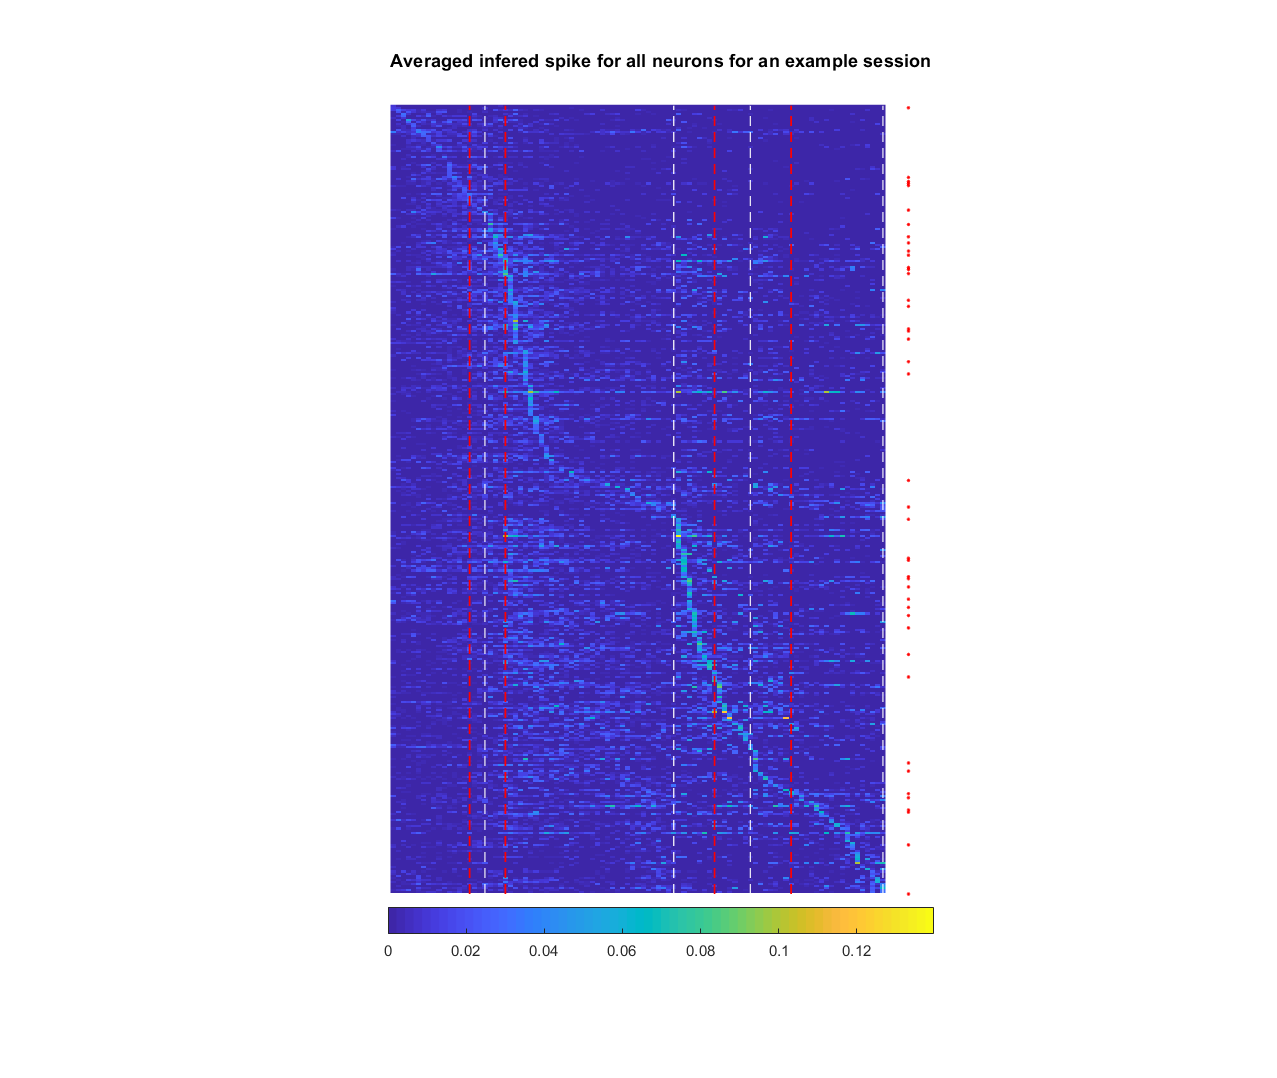

% Raster Plot - Figure 1E
fig1E = figure('Units','normalized', 'Position', [0.5, 0.5, 0.8, 1.2]);
ax1 = axes(fig1E);
hold on
imagesc(ax1, data_all)
% add vertical lines
cs = cumsum(xdim_all);
for z = 1: numel(zeros_all)
    line([cs(z), cs(z)], [0, size(data_all,1)], 'LineWidth', 0.7, 'Color','w','LineStyle','--')
    line([zeros_all(z), zeros_all(z)], [0, size(data_all,1)], 'LineWidth', 1, 'Color','r','LineStyle','--')
end
% add inhibitor marker
plot(ones(size(is_inh))*(size(data_all,2)+5), [1:numel(is_inh)].*is_inh', 'r.', 'MarkerSize', 5)

hold off
set(ax1, 'PlotBoxAspectRatio', [2, 3, 1], 'XTickLabel', [], 'YTickLabel', [])
set(ax1, 'XLim', [0, size(data_all, 2) + 10])
xlabel('Time'), ylabel('Neuron')
title('Averaged infered spike for all neurons for an example session')
colorbar('southoutside')
axis off

Similarly, minor data conditioning is required for the reproduction of Figure 1F

Trial-related information is stored in NWB 2.0 under **trials**. **trials** is a table-like data structure that enforces two required variables as table columns: *start_time*and *stop_time*. User can define any number of additional table columns to store trial-specific information related to their study.

Here, we have added 10 additional columns: *trial_type*, *trial_pulse_rate*, *trial_response*, *trial_is_good*, *init_tone*, *stim_onset*, *stim_offset*, *go_tone*, *first_commit*, *second_commit*

% Get trial info
trial_set = nwbfile.intervals.get('trials');

For the reproduction of Figure 1F, we wish to extract neuronal responses of *excitatory* and *inhibitory* neurons, separated by *trial type* category of either *High Rate* or *Low Rate*, and constrained by the condition that the mouse's response for this trial is correct

trial_is_good = trial_set.vectordata.get('trial_is_good').data.load;
trial_response_type = trial_set.vectordata.get('trial_response').data;
trial_type = trial_set.vectordata.get('trial_type').data;

% make trial-mask for correct high-rate (ipsilateral-lick) and low-rate (contralateral-lick) trial
correct_high_rate_trial = strcmp(trial_response_type,'correct') & strcmp(trial_type, 'High-rate');
correct_low_rate_trial = strcmp(trial_response_type,'correct') & strcmp(trial_type, 'Low-rate');

% make mask of inhibitory and excitatory neuron
is_inh = strcmp(neuron_type, 'inhibitory');
is_exc = strcmp(neuron_type, 'excitatory');

% specify event of interest to extract trial data 
tmp_eve = {'dFoF_initToneAl', 'dFoF_stimAl_noEarlyDec', 'dFoF_firstSideTryAl', 'dFoF_rewardAl'};
tmp_pre = [-10000, -100, -250, -250];
tmp_post = [100, 10000, 250, 10000];
segmentation_settings = [];
for k = 1:numel(tmp_eve)
    segmentation_settings(k).event = tmp_eve(k);
    segmentation_settings(k).pre = tmp_pre(k);
    segmentation_settings(k).post = tmp_post(k);
end

% extract trial-based data and average over trial
trial_avg_segments = struct();
for s = 1: numel(segmentation_settings)
    % extract segment
    out = get_trialsegmented_roi_timeseries(segmentation_settings(s).event, segmentation_settings(s).pre, segmentation_settings(s).post, trial_seg_module);
    % mask by high/low rate trial and inh/exc neuron type
    exc_correct_hr = out{1}(:, :, correct_high_rate_trial);
    exc_correct_hr = exc_correct_hr(is_exc, :, :);
    inh_correct_hr = out{1}(:, :, correct_high_rate_trial);
    inh_correct_hr = inh_correct_hr(is_inh, :, :);
    exc_correct_lr = out{1}(:, :, correct_low_rate_trial);
    exc_correct_lr = exc_correct_lr(is_exc, :, :);
    inh_correct_lr = out{1}(:, :, correct_low_rate_trial);
    inh_correct_lr = inh_correct_lr(is_inh, :, :);
    % take average across trials
    trial_avg_segments.(segmentation_settings(s).event{1}).exc_correct_hr = nanmean(exc_correct_hr, 3);
    trial_avg_segments.(segmentation_settings(s).event{1}).inh_correct_hr = nanmean(inh_correct_hr, 3);
    trial_avg_segments.(segmentation_settings(s).event{1}).exc_correct_lr = nanmean(exc_correct_lr, 3);
    trial_avg_segments.(segmentation_settings(s).event{1}).inh_correct_lr = nanmean(inh_correct_lr, 3);
    trial_avg_segments.(segmentation_settings(s).event{1}).timestamps = out{2}';
end    

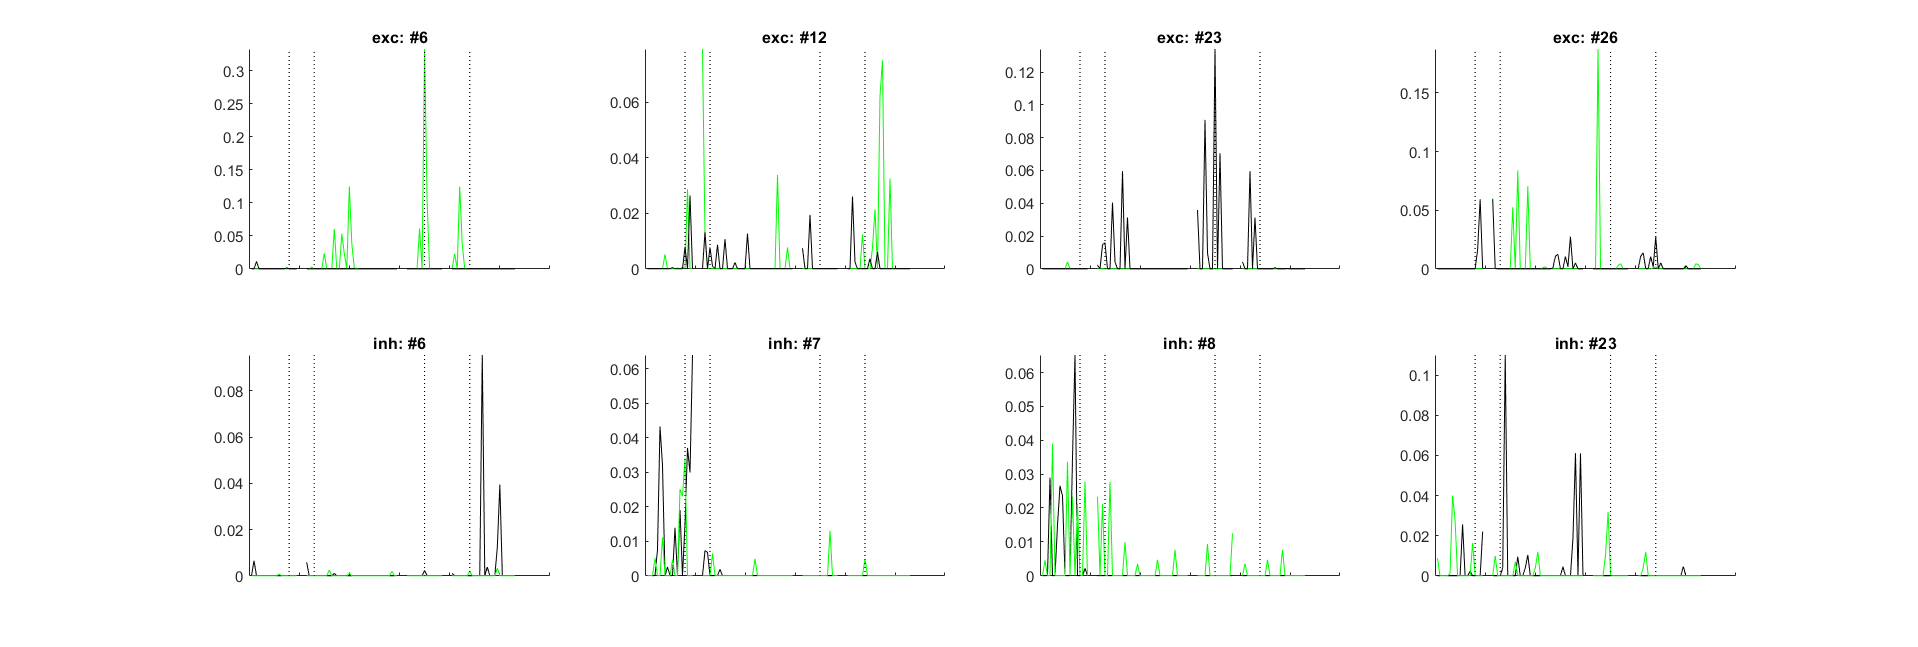

% Plot figure 1F
exc_idx = [6, 12, 23, 26];
inh_idx = [6, 7, 8, 23];

fig1F = figure('Units','normalized', 'Position', [0.5, 0.5, 1, 0.6]);
for k = 1:numel(exc_idx)
    exc_ax = subplot(2, numel(exc_idx), k);
    inh_ax = subplot(2, numel(exc_idx), k + numel(exc_idx));
    plot_sub_fig1F(exc_ax, inh_ax, trial_avg_segments, exc_idx(k), inh_idx(k)) 
end

Reproduction of Figure 1H

From all session, obtain neuron inferred spike activity (average of 3-frames before choice) for inhibitory and excitatory neurons.

Since each NWB 2.0 represent data from a single recording session, we will iterate through all session and extract the mean spiking response in ~100 ms prior to the time of *first commit* (*choice*-event) for all *inhibitory* and *excitatory* neurons

choice_event_key = 'dFoF_firstSideTryAl';
pre_dur = -97;
post_dur = 0;

trial_avg_inh_rois = []; trial_avg_exc_rois = []; inh_counts = []; exc_counts = [];
fnames = dir(data_dir);
for k = 1: numel(fnames)
    if fnames(k).isdir, continue; end
    % Read NWB 2.0 file
    fname = fnames(k).name;
    nwbfile = nwbRead(fullfile(data_dir, fname));
    trial_seg_module = nwbfile.processing.get('Trial-based-Segmentation').nwbdatainterface;
    
    % Obtain inh/exc status of the ROI
    roi_tcourse = trial_seg_module.get('dFoF_initToneAl').roiresponseseries.get('Trial_00'); 
    good_roi_mask = roi_tcourse.rois.deref(nwbfile).data.load; 
    roi_table = roi_tcourse.rois.deref(nwbfile).table.refresh(nwbfile);  
    neuron_type = roi_table.vectordata.get('neuron_type').data(good_roi_mask + 1);  % +1 to account for python 0-based indexing
    is_inh = strcmp(neuron_type, 'inhibitory');
    is_exc = strcmp(neuron_type, 'excitatory');    
    
    % Get trial status
    trial_set = nwbfile.intervals.get('trials');
    trial_is_good = strcmp(trial_set.vectordata.get('trial_is_good').data.load, 'TRUE');
    
    % Get data
    roi_ts = get_trialsegmented_roi_timeseries(choice_event_key, pre_dur, post_dur, trial_seg_module);
    roi_ts = roi_ts{1}(:, :, trial_is_good);
    
    % take average over 3 time points, then average over trials
    trial_avg_inh_rois = [trial_avg_inh_rois; nanmean(nanmean(roi_ts(is_inh, :, :), 2), 3)];
    trial_avg_exc_rois = [trial_avg_exc_rois; nanmean(nanmean(roi_ts(is_exc, :, :), 2), 3)];
    inh_counts(end + 1) = size(roi_ts(is_inh, :, :), 1);
    exc_counts(end + 1) = size(roi_ts(is_exc, :, :), 1);
end 

% process and plot Figure 1H
spike_val_vec = logspace(-3, 0, 1000);
exc_roi_frac = sum(trial_avg_exc_rois > spike_val_vec, 1) / numel(trial_avg_exc_rois);
inh_roi_frac = sum(trial_avg_inh_rois > spike_val_vec, 1) / numel(trial_avg_inh_rois);

fprintf('Total Excitatory neurons: %d - Inhibitory neurons: %d', sum(exc_counts), sum(inh_counts))

Total Excitatory neurons: 44546 - Inhibitory neurons: 5530

fprintf('Average Excitatory neurons: %.0f - Inhibitory neurons: %.0f', mean(exc_counts), mean(inh_counts))

Average Excitatory neurons: 330 - Inhibitory neurons: 41

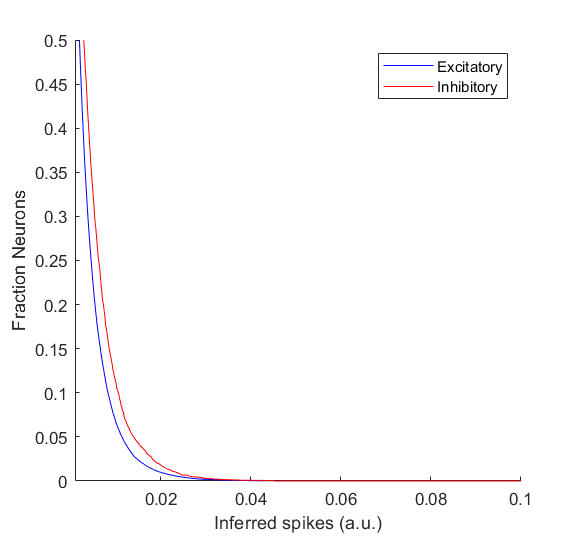

fig1H = figure('Units','normalized', 'Position', [0.5, 0.5, 0.3, 0.5]);
hold on
semilogx(spike_val_vec, exc_roi_frac, 'b')
semilogx(spike_val_vec, inh_roi_frac, 'r')
hold off
legend('Excitatory', 'Inhibitory')
ylabel('Fraction Neurons')
xlabel('Inferred spikes (a.u.)')
xlim([1e-3, 1e-1])
ylim([0, 0.5])

**Supporting functions**

function output = get_trialsegmented_roi_timeseries(event_name, pre_stim_dur, post_stim_dur, trial_seg_module)
    event_roi_timeseries = trial_seg_module.get(event_name).roiresponseseries;
    tvec = event_roi_timeseries.get('Trial_00').timestamps.load;  % timestamps from all trial are the same, so get one from trial_0
    % check if pre/post stim duration is out of bound
    pre_stim_dur = max(tvec(1), pre_stim_dur);
    post_stim_dur = min(tvec(end), post_stim_dur); 
    % extract data
    ix = (tvec >= pre_stim_dur) & (tvec <= post_stim_dur);
    out = [];
    trials = event_roi_timeseries.keys;
    for tr = 1: numel(trials)
        d = event_roi_timeseries.get(trials(tr)).data.load';  % tranpose here because matlab extract the data tranposed (time x roi)
        out(:, :, end+1) = d(:, ix);
    end
    out(:, :, 1) = [];
    output = {out, tvec(ix)};
end   

function plot_sub_fig1F(exc_ax, inh_ax, trial_avg_segments, exc_idx, inh_idx)    
    % make a nan-padding between each dataset 
    pad_size = 3;
    nan_padding = nan([1, pad_size]);
    
    exc_correct_hr = []; exc_correct_lr = []; inh_correct_hr = []; inh_correct_lr = []; tvec = [];
    fields = fieldnames(trial_avg_segments);
    for f = 1: numel(fields)
        exc_correct_hr = [exc_correct_hr, trial_avg_segments.(fields{f}).exc_correct_hr(exc_idx, :), nan_padding];
        exc_correct_lr = [exc_correct_lr, trial_avg_segments.(fields{f}).exc_correct_lr(exc_idx, :), nan_padding];
        inh_correct_hr = [inh_correct_hr, trial_avg_segments.(fields{f}).inh_correct_hr(inh_idx, :), nan_padding];
        inh_correct_lr = [inh_correct_lr, trial_avg_segments.(fields{f}).inh_correct_lr(inh_idx, :), nan_padding];
        tvec = [tvec, trial_avg_segments.(fields{f}).timestamps, nan_padding];
    end
    t_zeros = find(tvec == 0);
    
    % Plot
    axes(exc_ax)
    hold on 
    plot(exc_correct_hr, 'g')
    plot(exc_correct_lr, 'k')
    for z = 1: numel(t_zeros)
        line([t_zeros(z), t_zeros(z)], [0, nanmax([exc_correct_lr(:); exc_correct_hr(:)])], 'LineWidth', 0.7, 'Color','k','LineStyle',':')
    end
    hold off
    set(exc_ax, 'xticklabel', [], 'ylim', [-0.1e-3, nanmax([exc_correct_lr(:); exc_correct_hr(:)])])
    title(['exc: #', num2str(exc_idx)])
    
    axes(inh_ax)
    hold on 
    plot(inh_correct_lr, 'k')
    plot(inh_correct_hr, 'g')
    for z = 1: numel(t_zeros)
        line([t_zeros(z), t_zeros(z)], [0, nanmax([inh_correct_lr(:); inh_correct_hr(:)])], 'LineWidth', 0.7, 'Color','k','LineStyle',':')
    end
    hold off
    set(inh_ax, 'xticklabel', [], 'ylim', [-0.1e-3, nanmax([inh_correct_lr(:); inh_correct_hr(:)])])
    title(['inh: #', num2str(inh_idx)])   
end
